# Playing Wordle using your bot

Create a Live Script that helps you win when playing Wordle on the NYTimes site. The bot makes suggestions, then you tell the bot the word you played and the result. The bot makes another suggestion and you continue until you win or lose.

## Playing the game

Playing Wordle with the Bot should look like this game.

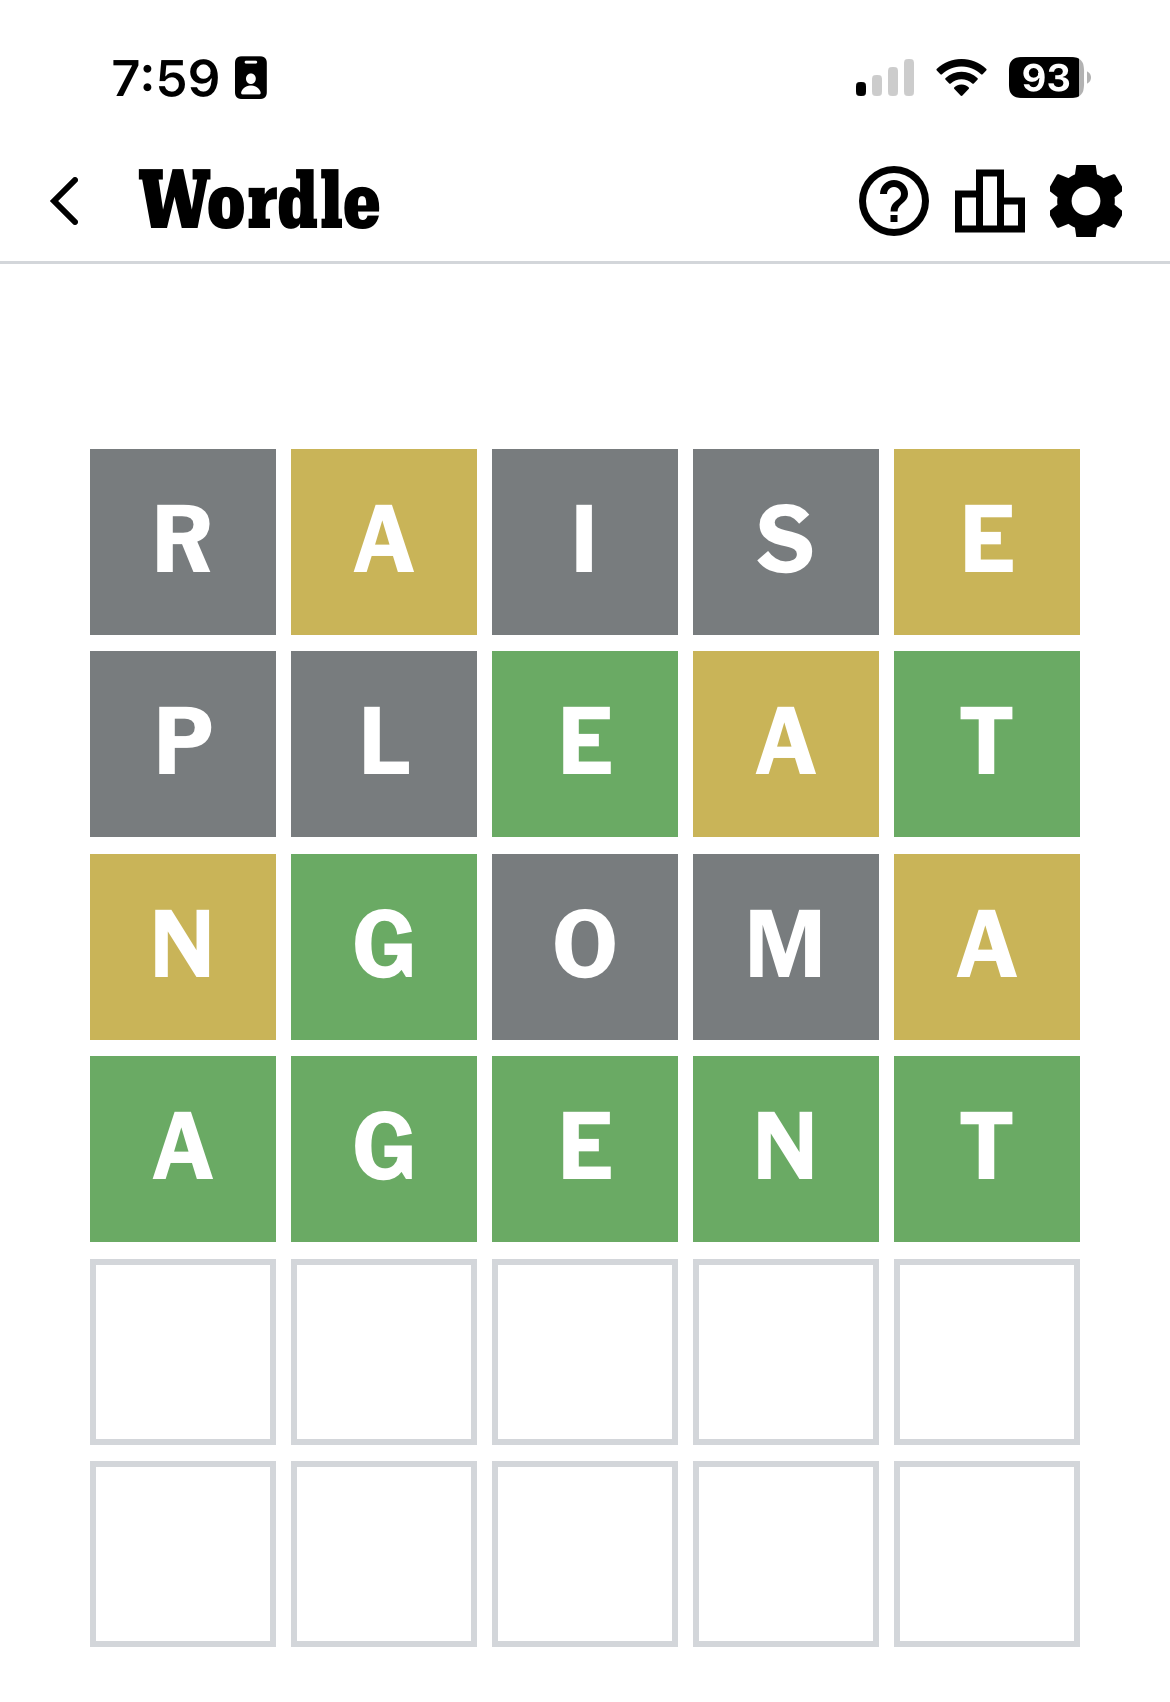

My WordleBot helped me with this puzzle like this:

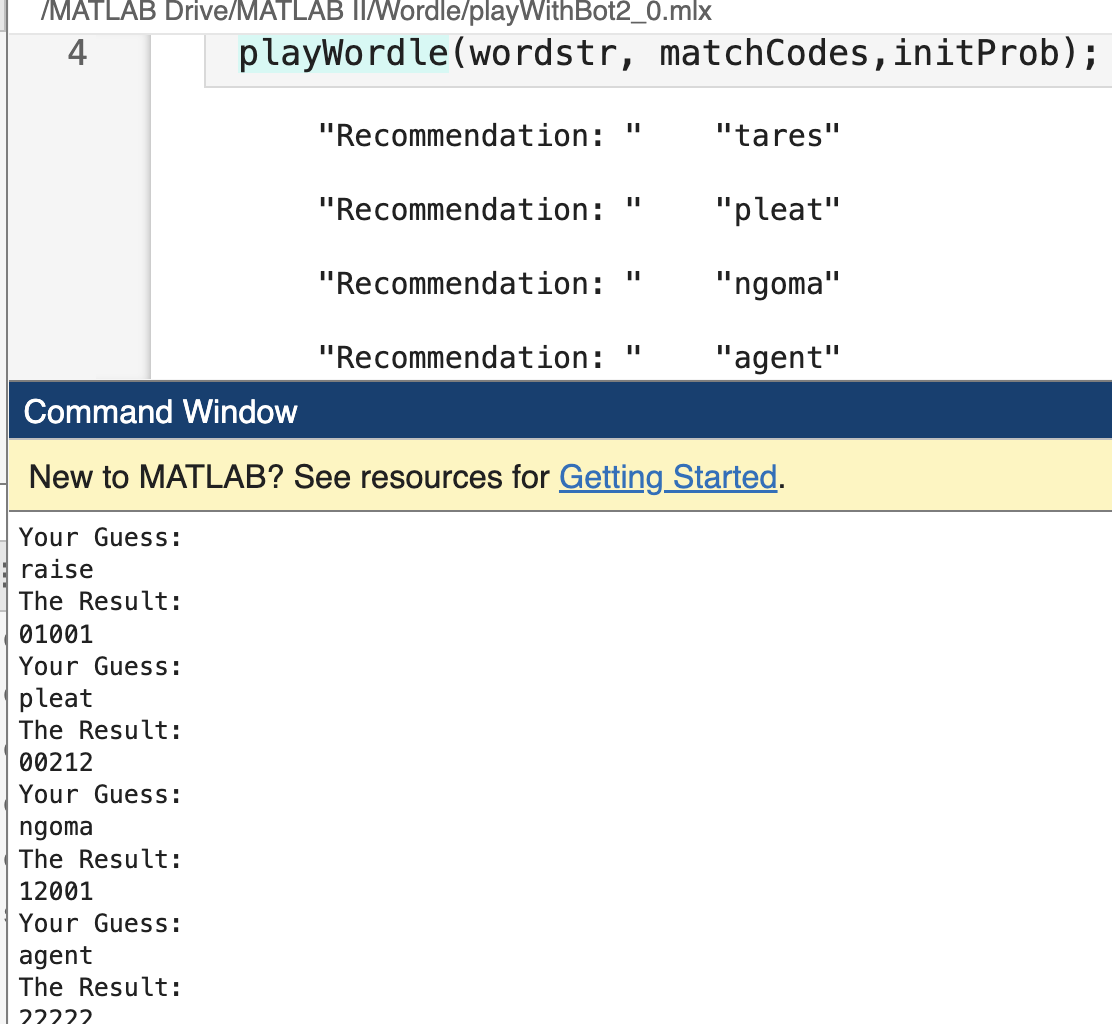

Notice the order of events:

- The bot makes a suggestion ("tares")

- I ignored the suggestion and played my favorite ("raise")

- I tell the bot what word I played.

- I tell the bot the result using a 2 for green, a 1 for yellow, and a 0 for grey.

- The bot makes another suggestion.

- After that I followed the suggestions and reported the results until I won.

Your bot will play the game similarly.  For now, we will use keyboard inputs and outputs to communicate with the bot.

### Reading input from the user

Display recommendation suing the `disp` function and read input from the user using the `input` function:

        disp(["Recommendation: " recommendation]);
        guess = input("Your Guess: ", "s");
        resultb3 = input("The Result: ", "s");

Notice that the result is in base-3 and need to be converted to decimal.

## Functions you need

You need to have completed the following actions and functions:

- You need to have generated a matrix of match codes and stored it in a `.mat` file so you can read it in at the beginning of your program.

- You need the `findprobabilities()` function to find the probability matrix after every guess.

- You need the `findguess()` function to find the next guess.

## The basic algorithm

Your program follows this algorithm.

First, you read in the match code matrix and the initial probability matrix.s:

if ~exist("matchCodes", 'var')
    load ../matchCodes.mat
end

Use the initial probability matrix to find the best first guess across all possible solutions.

Suggest the word to the user and then follow this algorithm:

- Get the word the user chose.

- Get the match code the user saw.

- Use the guess and the matchcode to find all the matching columns in the matchcode matrix.

- Use the matchcode to filter out the matching columns to match the remaining columns

- Find a new probability matrix using the remaining columns

- Find a new guess and show it to the user.

Repeat until the end.